# Heat and Flow Homework Assignment 3

© 2020 Jelle Langedijk, 1315358. j.langedijk@student.tue.nl  

#### Run every section individually, then read the values of variables form the workspace.

# **Q1 - Heat balance wall**

### A wall with an inner surface temperature T_in [C] is cooled down at its outer surface by blowing air with a temperature of T_inf = [C] over it. At steady state, the outer surface temperature has reached a temperature of T_out [C]. The thickness of the wall is dx [cm] and the wall-to-air heat transfer coefficient is h [W/mK]. What is the heat conduction coefficient (k) of the wall  in W/(mK)?

Since there is steady state, q"k = q"c. Then solve for k.

clc; close all; clear all;

T_in = 750;
T_inf = 250;
T_out = 500;
dx = 8;
h = 6;

k = (dx/100*h*(T_inf-T_out))/(T_out-T_in)

k = 0.4800

# **Q2 - Thermal network composite wall**

### A composite wall consists of two parts A and B. The outer surface of part A is in contact with a flowing fluid at a temperature  T_f [C] and a convective heat transfer coefficient h [W/mK]. The heat conduction coefficient of both parts (k_a , k_b) and the thickness L_a are known. The outer surface temperature of part A and B are T_a [C] and  T_b [C], respectively. The heat transfer of the fluid to the composite wall is only due to convection. Assume steady-state. In this problem we are interested in the thickness of part B.

clc; close all; clear all;

T_f=550;
h=5;
k_a=3;
k_b=0.5;
L_a=0.16;
T_a=450;
T_b=18;


### (1) First, determine the total thermal resistance of the wall sum_R , composed of the 2 conduction heat resistances R_a  and R_b . *(Note: Because the surface area of the composite wall is not known (and also  not needed because we are considering a 1-dimensional problem here),  write the heat balances in W/m^2 (A = 1 m^2) instead of W. This will result in heat resistances with dimension m^2K/W instead of K/W.)*

Steady State = q"c = q"k , where q"k = (T_a-T_b)/(sum_R) [conduction] and q"c = h(T_inf-T_s) = h(Tf-Ta) [convection]. Now solve for sum_R.  

sum_R=(T_a-T_b)/(h*(T_f-T_a))

sum_R = 0.8640

### (2) Then, determine the thickness L_b of part B by using sum_R .

L_b = (sum_R*k_a*k_b-L_a*k_b)/(k_a)

L_b = 0.4053

# **Q3 - Differential energy equation**

### Below, the differental energy equation can be seen. Link the terms of the equation to the correct explanation.

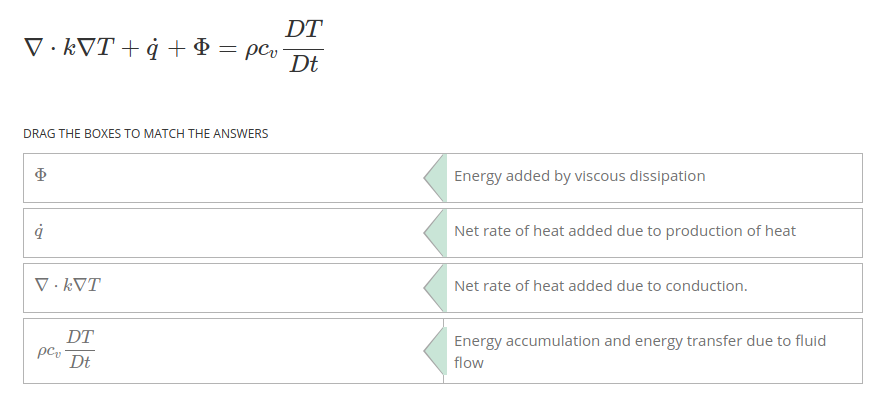

# **Q4 - Integral energy equation�**

### Below, the integral energy equation can be seen. Link the terms of the equation to the correct explanation.

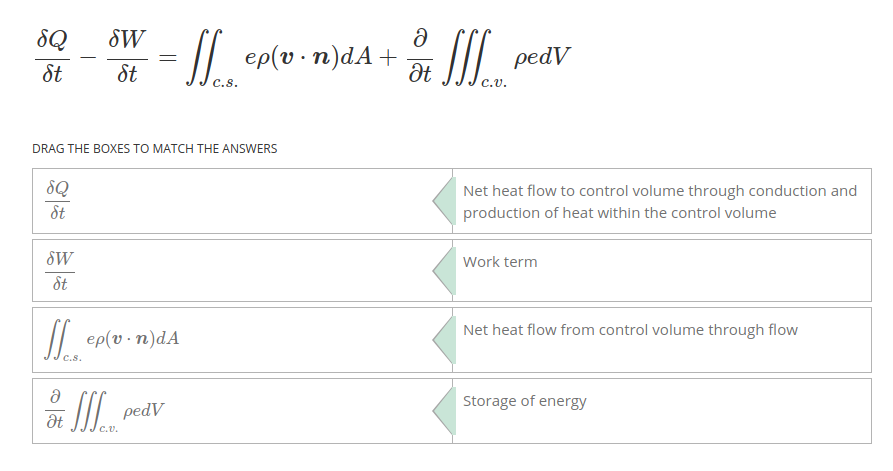

# **Q5 - Question 5: Hot steel cylindrical container**

### A hot fluid is stored in a cylindrical steel container with inside radius r_i [m] and outside radius r_o  [m]. The container is cooled by surrounding water via conduction  through the steel wall and convection to the ambient water. In this  problem we are interested in the one dimensional temperature profile  inside the steel wall in radial direction in steady state.

### **The energy equation for the steel wall reduces to the form:**


$$\nabla^{2}T =0 \rightarrow \frac{1}{r}\frac{d}{dr}(r\frac{dT}{dr}) = 0
$$


### In order to derive a function for the temperature profile in the hot  steel cylindrical wall, the following boundary conditions can be  applied:

### T = T_i at r = r_i ; T = T_o at r = r_o . The one dimensional temperature profile in the cylindrical wall can be written as:


$$T(r) = a \cdot ln(r) + b$$


Integration of the differential equation (as prove of T(r)) [NOT REQUIRED]:


$$\frac{1}{r}\frac{d}{dr}(r\frac{dT}{dr}) = 0
$$



$$
\frac{d}{dr}(r\frac{dT}{dr}) = 0
$$



$$
r\frac{dT}{dr} + C_1 = 0
$$



$$
\frac{dT}{dr} + \frac{C_1}{r} = 0

$$


$
T + ln(r)C_1 + C_2 = 0


$ (Note here that a and b are indeed negative in the final answer!)

Then substitute the boundary conditions (see for example ex 15.4 b)

clc; close all; clear all;
r_i=0.5;
r_o=0.6;
T_i=320;
T_o=35;



a=(T_o-T_i)/log(r_o/r_i)

a = -1.5632e+03

b=T_i-(((T_o-T_i)/log(r_o/r_i))*log(r_i))

b = -763.5084

# **Q6 - Steady heat generation in plane wall**

### In a plane wall a source is generating heat according to $\dot{q} = \dot{q_0}[1-\frac{x^2}{L^2}]$ where $\dot{q} = \frac{d^2T}{dx^2}
$ is the volumetric heat generation rate in W/m, $L$ is half the thickness of the plate, and $X$ is measured from the plate center line. What is the lowest temperature T_L  in the plate if the plate has a total thickness of t [cm] (which is 2  times L ), a volumetric heat generation rate of  qdot_0 = [W/m] and k [W/mK]. Assume that at x=0 , T = T_0  [C]. Beside this, it holds that at $x = 0
$, $\frac{dT}{dx}=0$.

Integration of the differential equation


$$\frac{d^2T}{dx^2} = \dot{q_0}[1-\frac{x^2}{L^2}]$$



$$\frac{dT}{dx}= - \frac{\dot{q_0}}{k}(x-\frac{x^3}{3L^2})+C_1$$


$C_1 = 0 $ (see boundary conditions)


$$T = -\frac{\dot{q_0}}{k}(\frac{x^2}{2}-\frac{x^4}{12L^2}) + C
_2$$


$C_2 = T_0

$  (see boundary conditions)

clc; close all; clear all;
t=19;
L=t/200;
qdot_0=28*10^4;
k=14;
T_0=200;
T_L=-1*(qdot_0/k)*((5*L^2)/12)+T_0

T_L = 124.7917

# **Q7 - Tip temperature cylindrical fin**

### A stainless steel cylindrical fin with k [W/mK] is used to increase the heat transfer from a surface. The surface has a temperature T_0 [C] and the ambient temperature T_inf [C]. The convection coefficient between the fin and the air  is h [W/mK]. The fin has a length L [mm] and a diameter D [mm]. Assume zero heat transfer from the tip of the fin to the ambient. What is the temperature T_xl at x = L ?�

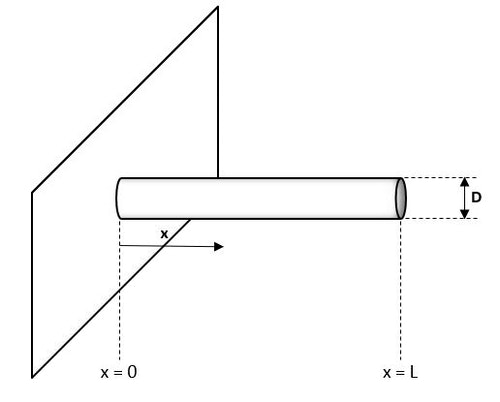

Fin problem:

$\frac{\theta}{\theta_0} = \frac{T-T_\infty}{T_0 - T_\infty} = \frac{cosh[mL(1-\frac{x}{L})]}{cosh[mL]}$ , where $m = \sqrt{\frac{hP}{kA}}$. Solve for T at x = L.  

clc; close all; clear all;
k=16;
T_0=210;
T_inf=23;
h=5;
L=280*0.001;
D=10*0.001;
A=(pi/4)*D^2;
P=pi*D;
m=sqrt((h*P)/(k*A));


T_xl =(((T_0-T_inf)*cosh(0))/cosh(m*L))+T_inf

T_xl = 39.3112

# **Q8 - Unsteady heat conduction - Dimensionless numbers�**

### A flat plate at an initial temperature $T_0$  is brought in contact with a convective environment of air at time $t=0$ . Below 4 different temperature distributions in the plate and the surrounding air are shown.

### Combine the correct values of the Biot (Bi) and Fourier (Fo) numbers (presented at the left) to the temperature distributions (shown at the right)�.  The Fourier number used here refers to the dimensionless time.�

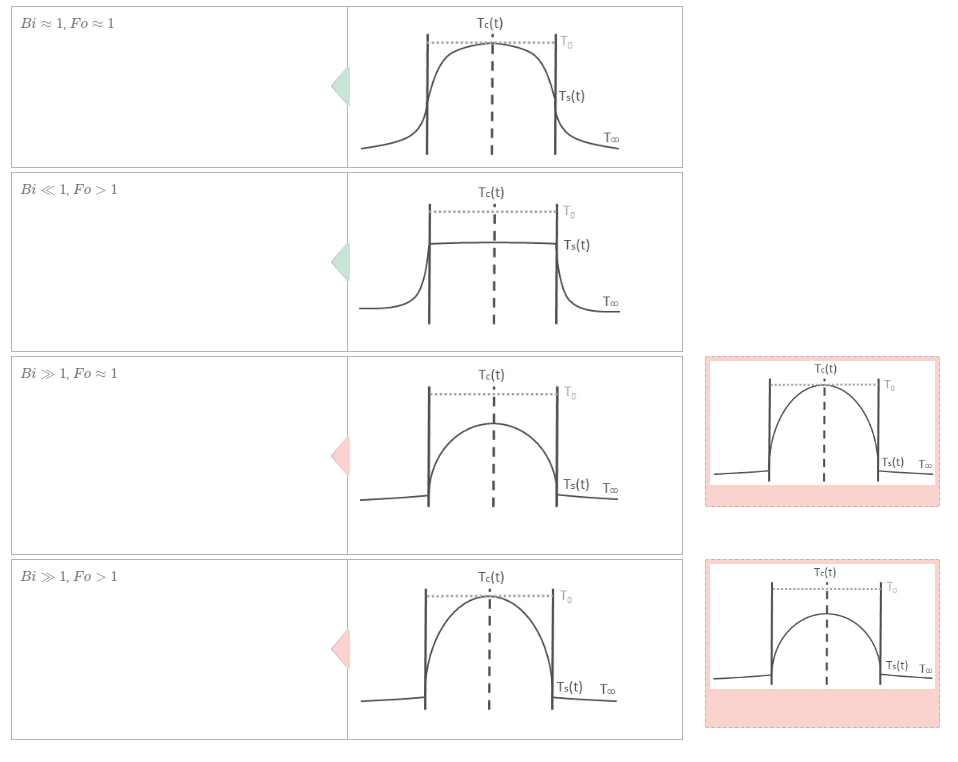

# **Q9 - Plate with unsteady-state conduction**

### A steel plate with a thickness t [mm] is heated up to T [C]. After that, the plate is cooled down at both sides to T_cool [C] by air of T_air [C] and a heat transfer coefficient h [W/mK]. The properties of steel are k [W/mK], rho  = 7800 [kg/m] and cp [J/kgK]. Determine the time (in minutes) required for the plate to reach a temperature of T_cool [C].

Unsteady State. Check if Lumped Capacitance Model can be used. This is the case when $Bi = \frac{hL_c}{k}   \ll 1$.

Lumped Capacitance Model: $\frac{T-T_\infty}{T_0 - T_\infty} = exp(-BiFo) = exp(-\frac{hAt
}{\rho Vc_p})$. Solve for $t$and convert to minutes.

clc; close all; clear all;

t=48*0.001;
T=700;
T_cool=100;
T_air=35;
h=14;
k=40;
rho=7800;
cp=600;
time=-1*((rho*t*cp)/(h*2))*log((T_cool-T_air)/(T-T_air));

Unrecognized function or variable 'Tside'.

time_minutes=time/60

# **Q10 - Unsteady-state conduction in a wall**

### A thick brick wall with a thickness L [m] has a temperature T [C]. The material properties of the brick wall are: k [W/mK], cp [J/kgK], rho [kg/m^3]. The left surface of the wall is suddenly exposed to hot air, such that the surface temperature of the wall remains constant at T_s [C]. Calculate the temperature of the center of the wall T_c after time_hour hours.

Unsteady State. Check if Lumped Capacitance Model can be used. This is the case when $Bi = \frac{hL_c}{k}   \ll 1$.

This is **not **the case! Use the similarity model: $\eta = \frac{x}{\sqrt{4\alpha t}}$ , $\frac{T-T_s}{T_0 - T_s} = erf(\eta)$. Solve for T.

clc; close all; clear all;

time_hour =6;
time =time_hour*3600;
L=0.5;
T=20;
k=1.2;
cp=905;
rho=2200;
T_s=900;
x=L/2;
alpha = k/(rho*cp);
eta=x/(sqrt(4*(alpha)*time));
T_c=T+((T_s-T)*(1-erf(eta)))